# **HW#1**

# **Sogol Goodarzi **

# **810198467**

# Part (1): Plotting the Cost Function

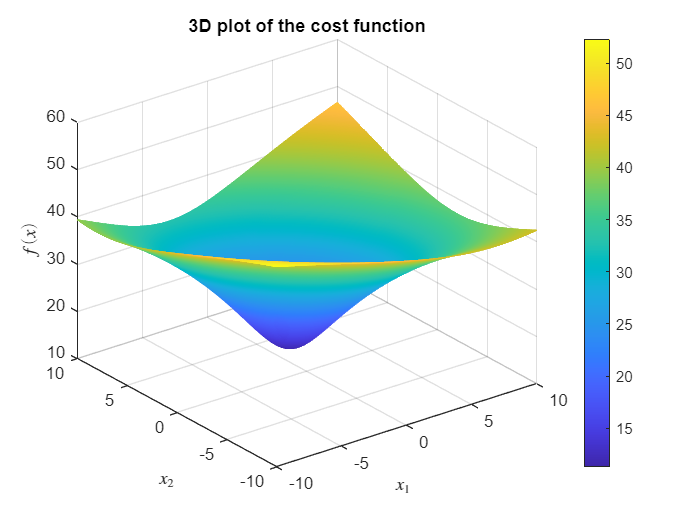

clear;
[X1,X2] = meshgrid(-10:.01:10);
F = X1.^2 + X2.^2 - 4*X1 - 6*X2 + 13 + X1.*X2;
mesh(X1,X2,db(F));
xlabel("$x_1$",Interpreter="latex");
ylabel("$x_2$",Interpreter="latex");
zlabel("$f(x)$",Interpreter="latex");
title("3D plot of the cost function")
colorbar

# Part (2): Plotting the Levels of Potential 

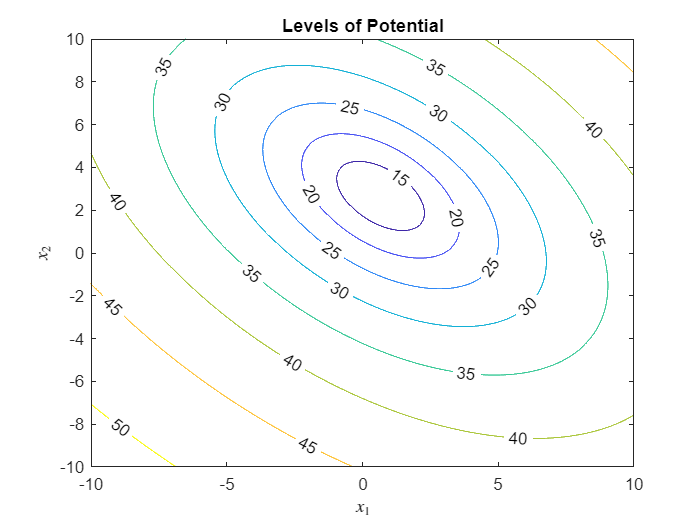

contour(X1,X2,db(F),"ShowText","on");
xlabel("$x_1$",Interpreter="latex");
ylabel("$x_2$",Interpreter="latex");
title("Levels of Potential")

# Part (5): Steepest Descend Method

###   
$$x_1 =x_2 =6$$


###  
$$\mathrm{for}\;\;\;\mu =0\ldotp 1$$


x1 = 6;  x2 = 6;
mu1 = 0.1;
x_k = [x1;x2];
threshold = 1e-6;
N = 1000;
a = [-4,-6]';
A = [0,1/2;1/2,0];
f(1) = x_k'*x_k + x_k'*a + 13 + x_k'*A*x_k;
for i=1:1:N 
    g = 2*x_k + a + A*x_k + A'*x_k;
    x_k = x_k - mu1*g;
    f(i+1) = x_k'*x_k + x_k'*a + 13 + x_k'*A*x_k;
    if(abs(f(i+1)-f(i))<threshold)
        break;
    end
end 
fprintf("The minimum point of the cost function is: \n x1 = %.4f \n x2 = %.4f",x_k(1),x_k(2));

The minimum point of the cost function is: 
 x1 = 0.6687 
 x2 = 2.6647

fprintf("The minimum value of the cost function is : %.4f",f(i));

The minimum value of the cost function is : 3.6667

fprintf("The minimum point is reached in %d iterations.",i);

The minimum point is reached in 59 iterations.

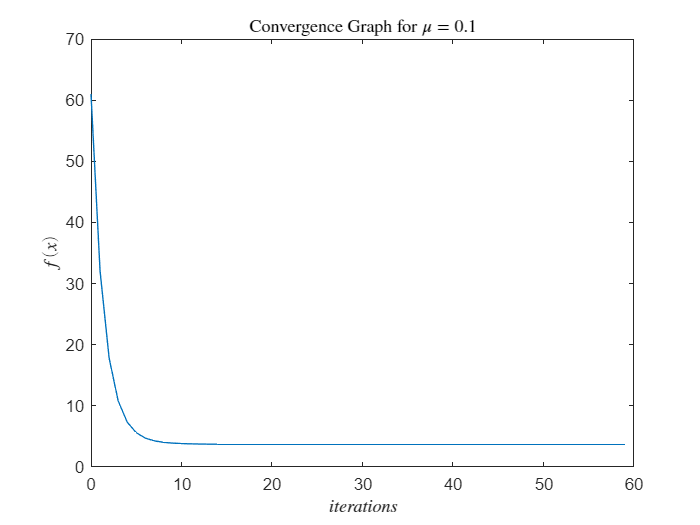

plot(0:i,f);
xlabel("$iterations$",Interpreter="latex");
ylabel("$f(x)$",Interpreter="latex");
title("Convergence Graph for $\mu=0.1$",Interpreter="latex")

###  
$$\;x_1 =x_2 =6$$


###  
$$\textrm{for}\;\;\;\mu =0\ldotp 01$$


clear;
x1 = 6;  x2 = 6;
mu2 = 0.01;
x_k = [x1;x2];
threshold = 1e-6;
N = 1000;
a = [-4,-6]';
A = [0,1/2;1/2,0];
f(1) = x_k'*x_k + x_k'*a + 13 + x_k'*A*x_k;
for i=1:1:N 
    g = 2*x_k + a + A*x_k + A'*x_k;
    x_k = x_k - mu2*g;
    f(i+1) = x_k'*x_k + x_k'*a + 13 + x_k'*A*x_k;
    if(abs(f(i+1)-f(i))<threshold) 
        break;
    end
end 
fprintf("The minimum point of the cost function is: \n x1 = %.4f \n x2 = %.4f",x_k(1),x_k(2));

The minimum point of the cost function is: 
 x1 = 0.6736 
 x2 = 2.6597

fprintf("The minimum value of the cost function is : %.4f",f(i));

The minimum value of the cost function is : 3.6667

fprintf("The minimum point is reached in %d iterations.",i);

The minimum point is reached in 494 iterations.

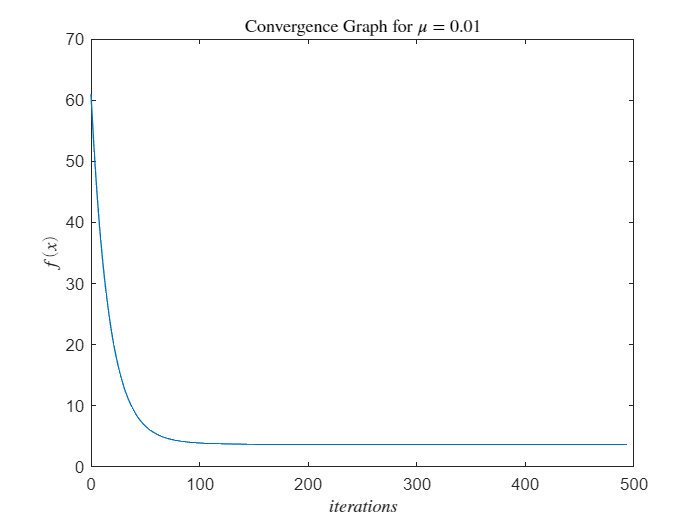

plot(0:i,f);
xlabel("$iterations$",Interpreter="latex");
ylabel("$f(x)$",Interpreter="latex");
title("Convergence Graph for $\mu=0.01$",Interpreter="latex")

# Part (6): Newton's Method

###  
$$\;x_1 =x_2 =6$$


clear;
x1 = 6;
x2 = 6;
x_k = [x1;x2];
threshold = 1e-6;
N = 1000;
a = [-4,-6]'; 
A = [0,1/2;1/2,0];
f(1) = x_k'*x_k + x_k'*a + 13 + x_k'*A*x_k;
for i=1:1:N 
    g = 2*x_k + a + A*x_k + A'*x_k;
    H = 2*eye(2)+2*A;
    x_k = x_k - inv(H)*g;
    f(i+1) = x_k'*x_k + x_k'*a + 13 + x_k'*A*x_k; 
    if(abs(f(i+1)-f(i))<threshold)
        break;
    end
end 
fprintf("The minimum point of the cost function is: \n x1 = %.4f \n x2 = %.4f",x_k(1),x_k(2));

The minimum point of the cost function is: 
 x1 = 0.6667 
 x2 = 2.6667

fprintf("The minimum value of the cost function is : %.4f",f(i));

The minimum value of the cost function is : 3.6667

fprintf("The minimum point is reached in %d iterations.",i);

The minimum point is reached in 2 iterations.

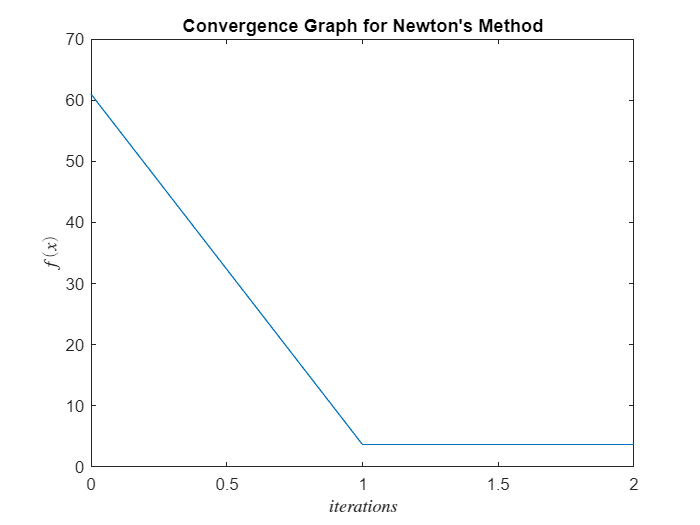

plot(0:i,f);
xlabel("$iterations$",Interpreter="latex");
ylabel("$f(x)$",Interpreter="latex");
title("Convergence Graph for Newton's Method")

# Part (7): Alternation Minimization Method

clear;
x1 = 6;
x2 = 6;
X_k = [x1;x2];
threshold = 1e-6;
N = 1000;
f_(1) = x1^2 + x2^2 - 4*x1 - 6*x2 + 13 + x1*x2;
j = 2;
for i=2:2:N
    x2 = (6-x1)/2;
    f_(i) = x1^2 + x2^2 - 4*x1 - 6*x2 + 13 + x1*x2; 
    X_k(1,i) = x1;
    X_k(2,i) = x2;
    if(abs(f_(i)-f_(i-1))<threshold)
        break;
    end
    x1 = (4-x2)/2;
    f_(i+1) = x1^2 + x2^2 - 4*x1 - 6*x2 + 13 + x1*x2; 
    X_k(1,i+1) = x1;
    X_k(2,i+1) = x2;    
    if(abs(f_(i+1)-f_(i))<threshold)
        break;
    end
end 
fprintf("The minimum point of the cost function is: \n x1 = %.4f \n x2 = %.4f",X_k(1,end),X_k(2,end));

The minimum point of the cost function is: 
 x1 = 0.6670 
 x2 = 2.6660

fprintf("The minimum value of the cost function is : %.4f",f_(i));

The minimum value of the cost function is : 3.6667

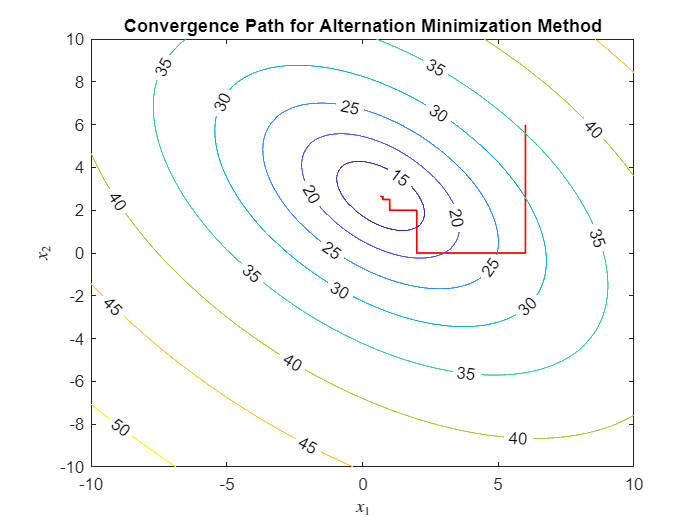

plot(X_k(1,:),X_k(2,:),"Color","r","LineWidth",1);
hold on
[X1,X2] = meshgrid(-10:.01:10);
F = X1.^2 + X2.^2 - 4*X1 - 6*X2 + 13 + X1.*X2;
contour(X1,X2,db(F),"ShowText","on");
xlabel("$x_1$",Interpreter="latex");
ylabel("$x_2$",Interpreter="latex");
title("Convergence Path for Alternation Minimization Method")
hold off

# Part (8): Gradiant Projection 

### 
$$\textrm{For}\;\;\mu =0\ldotp 1\;\textrm{with}\;\;\;S\ldotp D\;\;\textrm{method}$$


clear;
x1 = 6;  x2 = 6;
mu = 0.1;
x_k = [x1;x2];
threshold = 1e-6;
N = 1000;
a = [-4,-6]';
A = [0,1/2;1/2,0];
x_k = x_k/(sqrt((x_k(1))^2+(x_k(2))^2));
f(1) = x_k'*x_k + x_k'*a + 13 + x_k'*A*x_k;
for i=1:1:N 
    g = 2*x_k + a + A*x_k + A'*x_k;
    x_k = x_k - mu*g;
    x_k = x_k/(sqrt((x_k(1))^2+(x_k(2))^2));
    f(i+1) = x_k'*x_k + x_k'*a + 13 + x_k'*A*x_k;
    if(abs(f(i+1)-f(i))<threshold)
        break;
    end
end 
fprintf("The minimum point of the cost function is: \n x1 = %.4f \n x2 = %.4f",x_k(1),x_k(2));

The minimum point of the cost function is: 
 x1 = 0.4946 
 x2 = 0.8691

fprintf("The minimum value of the cost function is : %.4f",f(i));

The minimum value of the cost function is : 7.2367